## 浪花号18-b建模

- 使用6次多项式建模

- 要是觉得过拟合了，可以改成五次

- 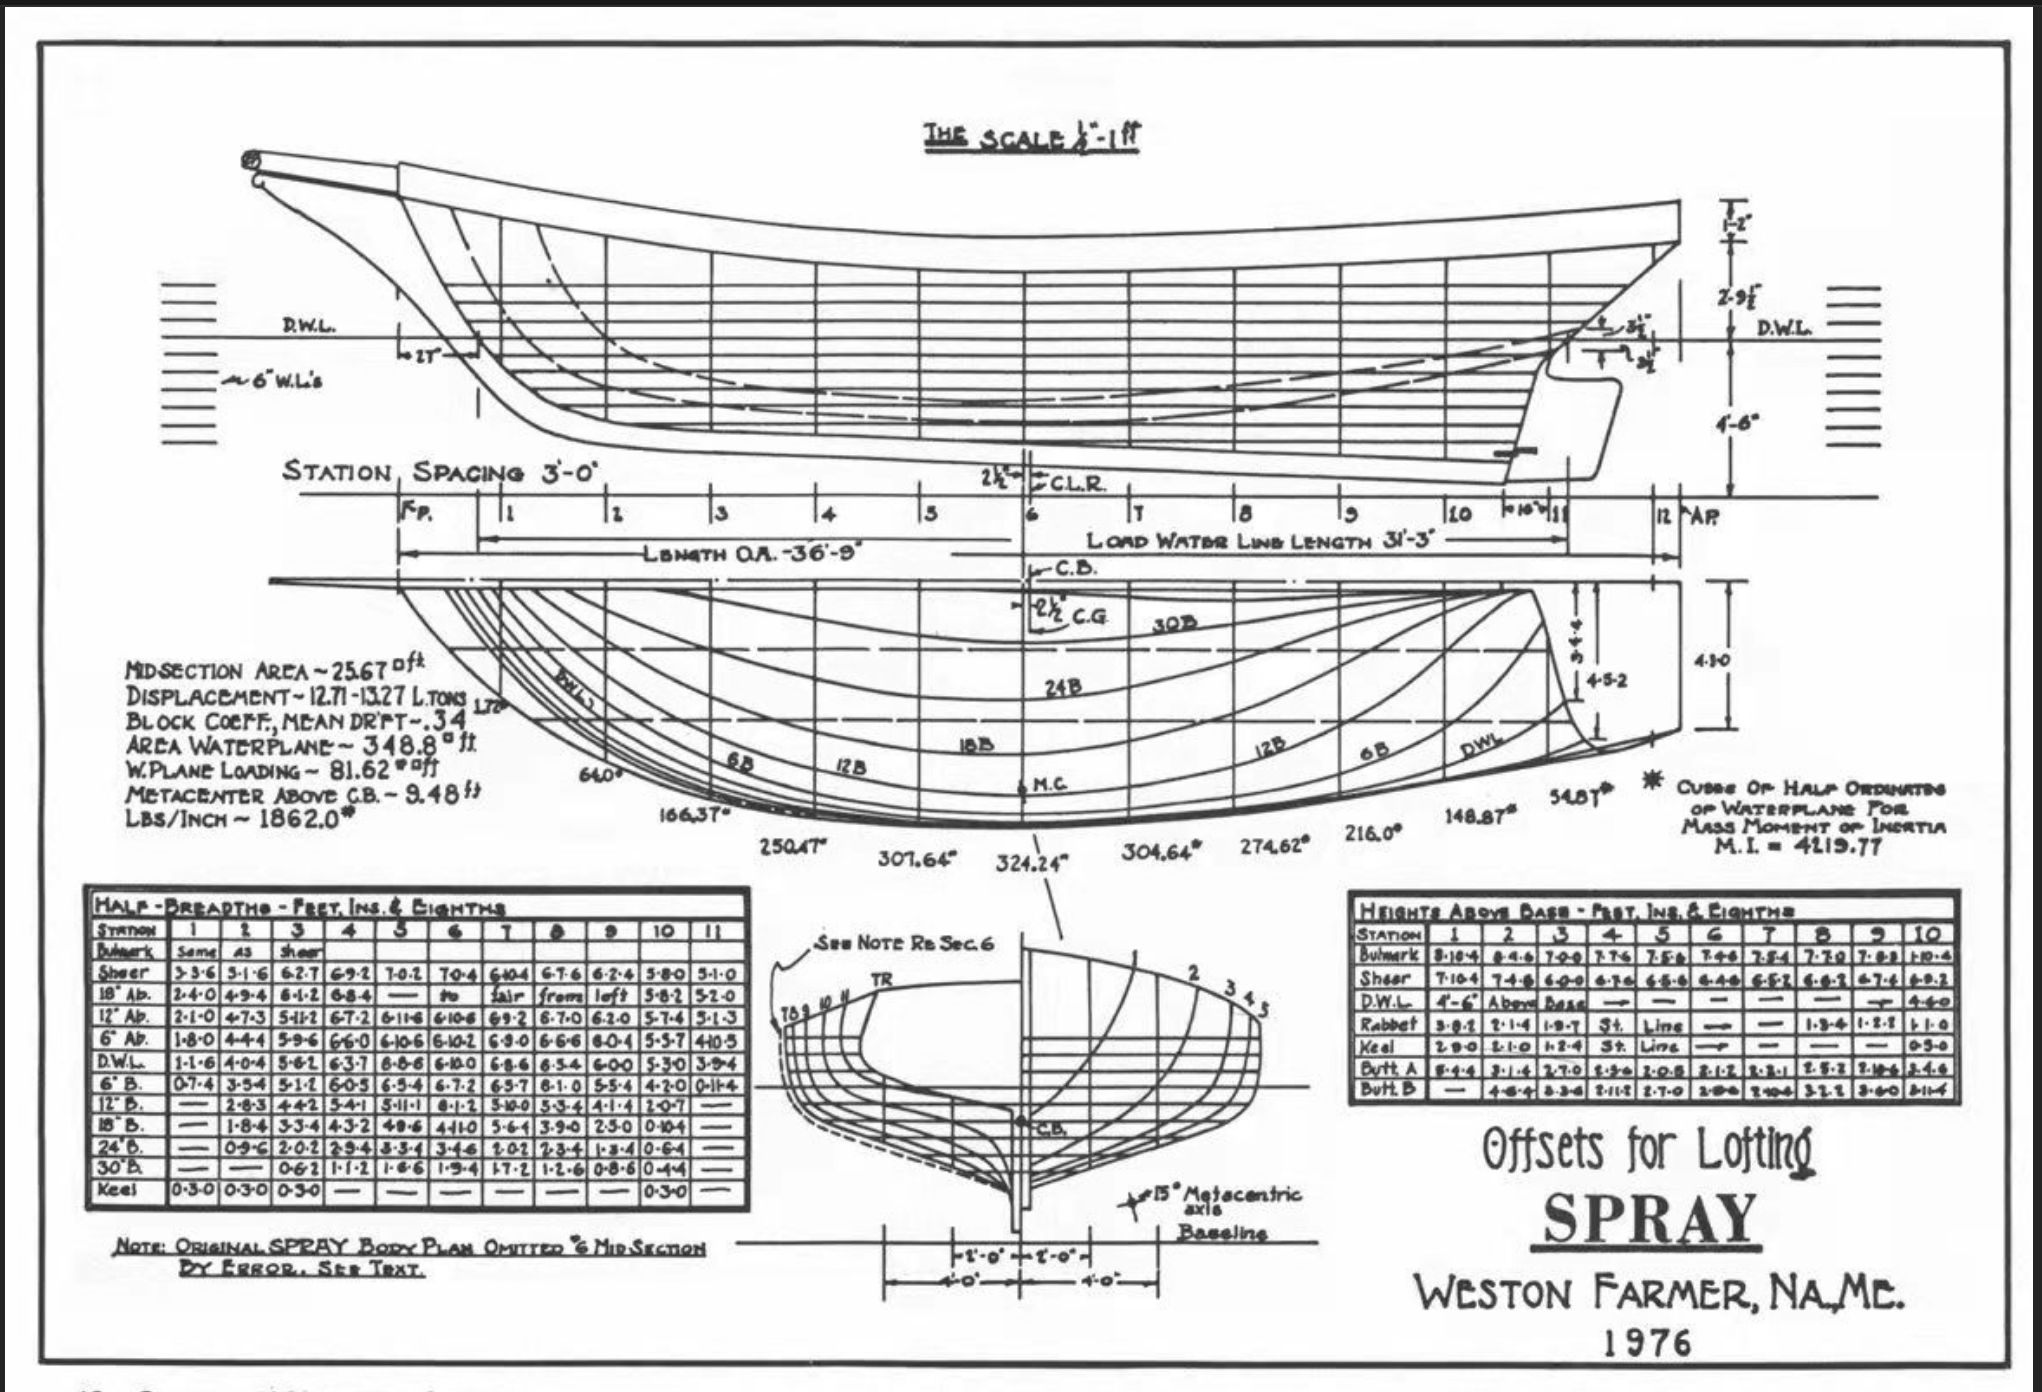

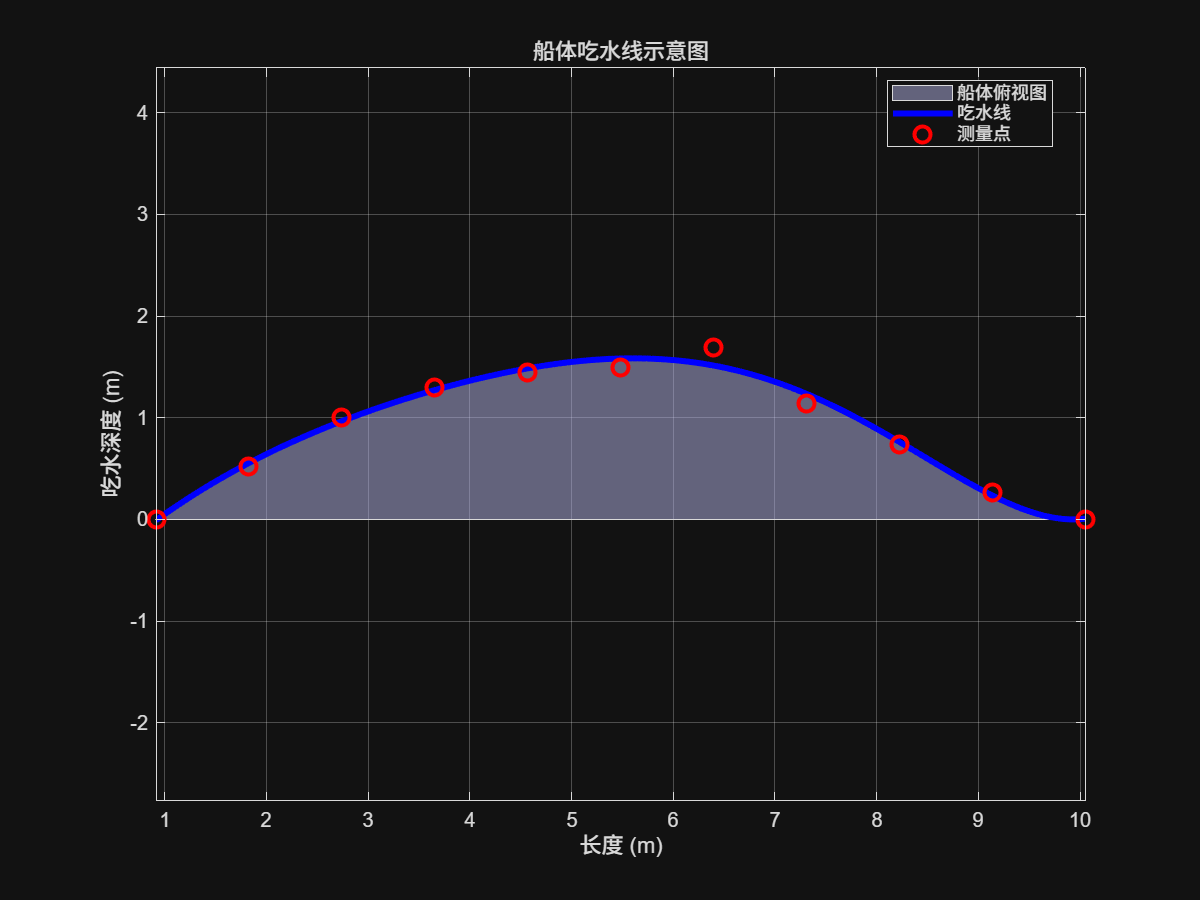

% 单位转换常数定义
unit = 0.9144;      % 1单位 = 0.9144米 
feet = 0.3048;      % 1英尺 = 0.3048米
inch = 0.0254;      % 1英寸 = 0.0254米

% 定义单位转换函数 A
% 输入参数：
%   i - 英尺数
%   j - 英寸数  
%   k - 1/8英寸的数量
% 输出：
%   res - 转换后的总长度（米）
function res = A(i, j, k)
    feet = 0.3048;      % 1英尺对应的米数
    inch = 0.0254;      % 1英寸对应的米数
    % 计算总长度：英尺转换 + 英寸转换 + 1/8英寸转换
    res = i * feet + j * inch + k * inch * 0.125;
end

% 船体测量点的x坐标（横向位置）
% 使用unit作为基本单位，从1到11个单位位置
x = [1*unit 2*unit 3*unit 4*unit 5*unit 6*unit 7*unit 8*unit 9*unit 10*unit 11*unit];

% 船体测量点的y坐标（吃水深度/船体高度）
% 使用A函数将英制单位转换为米制单位
% 每个点对应不同的英尺、英寸和1/8英寸组合
y = [0 A(1,8,4) A(3,3,4) A(4,3,2) A(4,8,6) A(4,11,0) A(5,6,4) A(3,9,0) A(2,5,0) A(0,10,4) 0];

% 多项式拟合参数设置
p_degree = 6;   % 选择6次多项式进行曲线拟合
                % 这个次数可以根据拟合效果调整，次数越高曲线越灵活

% 执行多项式拟合
% polyfit函数返回多项式系数，从最高次项到常数项排列
p = polyfit(x, y, p_degree);

% 生成更密集的x坐标点用于绘制平滑曲线
% linspace在最小值和最大值之间生成200个等间距点
x_fine = linspace(min(x), max(x), 200);

% 使用拟合的多项式计算密集点对应的y值
y_poly = polyval(p, x_fine);

% 创建图形窗口并设置位置和大小
figure('Position', [100, 100, 800, 600]);

% 绘制船体俯视图（填充区域）
% fill函数创建填充多边形：
%   [x_fine, fliplr(x_fine)] - x坐标正向再反向，形成闭合区域
%   [y_poly, zeros(size(y_poly))] - 上边界为拟合曲线，下边界为0（水面）
%   [0.7 0.7 0.9] - 浅蓝色填充颜色(RGB值)
%   'FaceAlpha', 0.5 - 设置50%透明度
fill([x_fine, fliplr(x_fine)], [y_poly, zeros(size(y_poly))], [0.7 0.7 0.9], 'FaceAlpha', 0.5);
% 保持当前图形，允许在同一图中添加更多元素
hold on;

% 绘制多项式拟合的吃水线
% 'b-' - 蓝色实线
% 'LineWidth', 3 - 线宽为3磅
plot(x_fine, y_poly, 'b-', 'LineWidth', 3);

% 绘制原始测量数据点
% 'ro' - 红色圆圈标记
% 'MarkerSize', 8 - 标记大小8磅
% 'LineWidth', 2 - 线宽2磅
plot(x, y, 'ro', 'MarkerSize', 8, 'LineWidth', 2);

% 设置坐标轴属性
axis equal    % x轴和y轴使用相同的刻度比例，保持图形不变形
grid on;      % 显示网格线

% 添加坐标轴标签
xlabel('长度 (m)');        % x轴标签：长度（米）
ylabel('吃水深度 (m)');    % y轴标签：吃水深度（米）

% 添加图形标题
title('船体吃水线示意图');

% 添加图例说明
% 分别对应：填充区域、拟合曲线、测量点
% 'Location', 'best' - 自动选择最佳位置放置图例
legend('船体俯视图', '吃水线', '测量点', 'Location', 'best');